filename = "elg_va"

filename = "elg_va"

filepath_org = "./data/" + filename + ".wav";
[org, fs] = audioread(filepath_org);
org = org(fs:2*fs);

%sound(s(1:fs*2), fs); pause(2.5)
duration = length(org) / fs;

spectol1 = abs(fft(org.*hamming(length(org))));


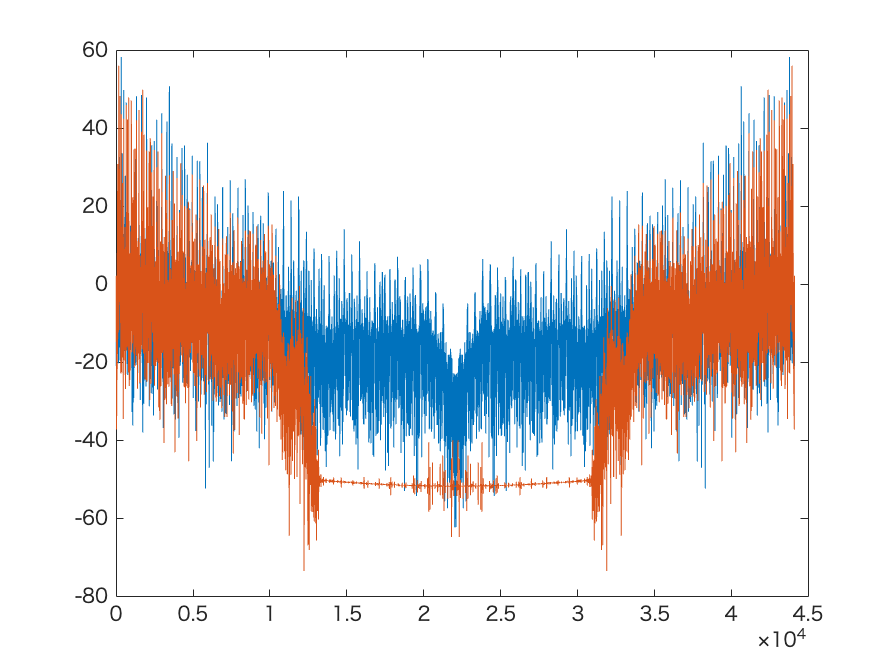

figure
plot(20*log10(spectol1));
hold on
[b,a] = biquad_highshelf(fs/4,10,0.6,fs);
org_shift = shiftPitch(filter(b,a,org), -12);
spectol2 = abs(fft(org_shift.*hamming(length(org))));

plot(20*log10(spectol2));